# SST hydrodynamic coefficients determination

## Axial drag

% Xuu
clear
l = 166; % SST length
rho = 1025;
d = 17; %SST Diameter
A_f = d^2/4*pi; %Hull frontal area
A_p = l*d; %Vehicle plan area
c_ss = 3.397e-3;
c_d = c_ss*pi*A_p/A_f*(1+60*(d/l)^3+0.0025*(l/d))

c_d = 0.1445

X_uu = -c_d*A_f/l^2

X_uu = -0.0012

## Cross flow drag

Find divide the SST along x direction into 3 parts: cone, cylinder, hemisphere

x_co = [0:0.2:24.8 25:0.5:157.5 157.6:0.1:166];

radius of the cone part

R(1:sum(x_co<=25)) = 8.5/25*x_co(1:sum(x_co<=25));

radius of the cylinder part

R(sum(x_co<=25):sum(x_co<=157.5)) = 8.5;

radius of the hemisphere part

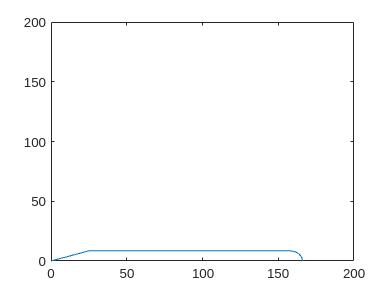

R(sum(x_co<=157.5):length(x_co)) = sqrt(8.5^2-(x_co(sum(x_co<=157.5):end)-157.5).^2);
plot(x_co,R)
xlim([0,200])
ylim([0,200])

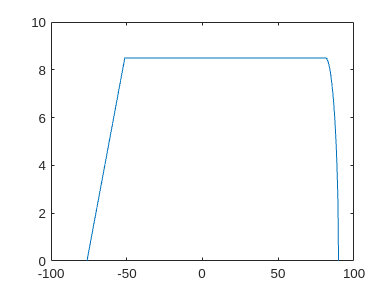


x_coor = x_co-8.5-0.5*(166-25-8.5)-1.51; %Move origin to CoG
plot(x_coor,R)

Nonlinear crossflow drag coefficients

c_dc = 1.1; % drag coefficient of cylinder by hoerner
Y_vv = -c_dc*trapz(x_coor,2*R)/l^2

Y_vv = -0.1029

Z_ww = Y_vv;
M_ww = c_dc*trapz(x_coor,2*x_coor.*R)/l^3

M_ww = 0.0074

N_vv = -M_ww;
Y_rr = -c_dc*trapz(2.*x_coor.*abs(x_coor).*R)/l^4

Y_rr = -0.0129

Z_qq = -Y_rr;
M_qq = -0.0714%-c_dc*trapz(x_coor,2*x_coor.^3.*R)/l^5

M_qq = -0.0714

N_rr = M_qq;

## Roll damping

calculated from the fins. No roll damping from hull

K_pp = 0;

## Added mass

Assume the SST is an ellipsoid

alpha = 0.02071;
X_ud = -4/3*alpha*pi*(d/2)^2/l^2

X_ud = -2.2745e-04

m_a = pi*rho*R.^2;
Y_vd = -trapz(x_coor,m_a)/(0.5*rho*l^3)

Y_vd = -0.0145

Z_wd = Y_vd;
M_wd = -trapz(x_coor,m_a.*x_coor)/(0.5*rho*l^4)

M_wd = -0.0012

N_vd = -M_wd;
Y_rd = N_vd;
Z_qd = M_wd;
M_qd = -trapz(x_coor,m_a.*x_coor.^2)/(0.5*rho*l^5)

M_qd = -0.0011

N_rd = M_qd;

added mass in roll consider fin only

K_pd = 0;

Cross terms

X_wq = Z_wd;
X_qq = Z_qd;
X_vr = -Y_vd;
X_rr = -Y_rd;
Y_ur = X_ud;
Y_wp = -Z_wd;
Y_pq = -Z_qd;
Z_uq = -X_ud;
Z_vp = Y_vd;
Z_rp = Y_rd;
M_uwa = -(Z_wd-X_ud);
M_vp = -Y_rd;
M_rp = (K_pd-N_rd);
M_uq = -Z_qd;
N_uva = -(X_ud-Y_vd);
N_wp = Z_qd;
N_pq = -(K_pd-M_qd);
N_ur = Y_rd;

## Body lift

Y_uvl = -d/l*180/pi*0.003

Y_uvl = -0.0176

Z_uwl = Y_uvl;
x_cp = -166*0.65+1.51+0.5*(166-8.5-25)+8.5

x_cp = -31.6400

M_uwl = Y_uvl*x_cp/l

M_uwl = 0.0034

N_uvl = -M_uwl;